## **Simulation for Active Structures -- A Living Textbook**

**by Yi Zhu (PhD)**

clear all; 
close all; 
clc;

***Please add "00_SourceCode_Elements" and "00_SourceCode_Solver" into path before running the code***

**Example 03 Laoding of Scissor Mechanism**

In the previous example, we showed how to simulate the deployment a scissor mechanism. Here, we want to see how we can capture the load-carrying behavior of the same system. 

 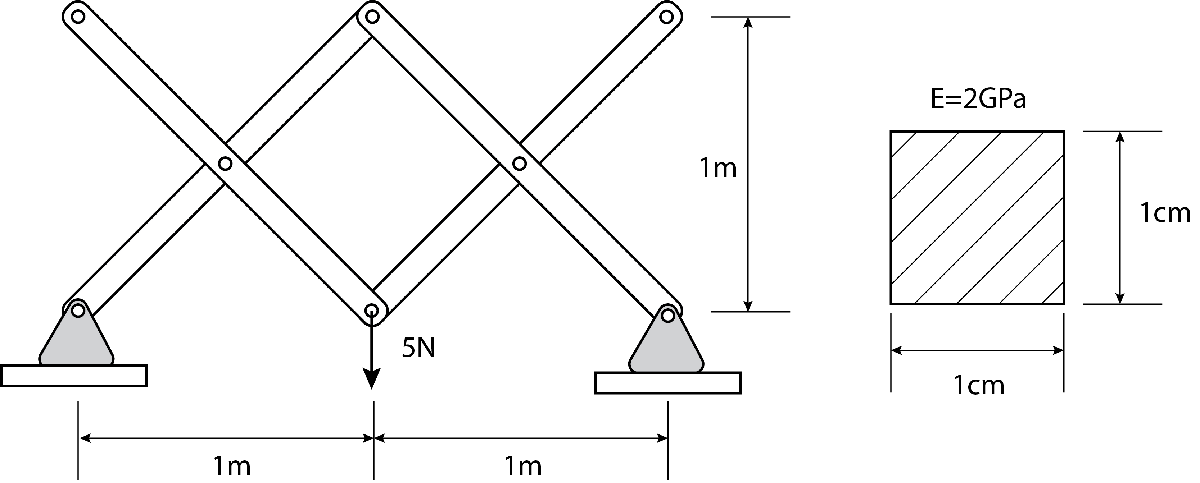

The above figure shows the loaing set up. Please do notice that the support information is changed. Now, both ends are fixed support - this will turn the mechanism into a structure. 

The set up of the simulation is mostly the same as the previous one so we will skip uncessary descriptions. 

clear all;
clc;
close all;

%% Initialize the truss
% Define the nodes
H=1; % Height of the truss
L=1; % Length of each span
barA=0.0001; % cross section area (m^2)
barE=2*10^9; % Youngs' modulus (Pa)

% We will also solve for the bending stiffness of the frame
I=1/12*0.01^4;
% When using four segment to represent a frame, 
% three rotational springs are used
% Using Larry Howell's pseudo rigid body model
% We can convert the bending stiffness to spring stiffness
barL=sqrt(H^2+L^2);
kspr=3*barE*I/barL;

Define all the objects for the elements we need to use

% Define the node object
node=Elements_Nodes;
% Create the bar object
bar=CD_Elements_Bars;
% Create the 3-node rot spring
rot_spr_3N=CD_Elements_RotSprings_3N;

% Create tje truss Assembly
assembly=Assembly_2D_Mechanism;
% This assembly has a node object and a bar object
assembly.node=node;
assembly.bar=bar;
assembly.rot_spr_3N=rot_spr_3N;

Here, the nodal coordinates of this example is the same as Example 02.

%% Define the nodal coordinates
% Here we need to set up the nodal coordinates of our truss
node.coordinates_mat=[0*L 0 0; 
                      1*L 0 0;
                      2*L 0 0; % Node 3
                      0*L 0 H;
                      1*L 0 H; 
                      2*L 0 H; % Node 6
                      0.5*L 0 0.5*H; 
                      1.5*L 0 0.5*H; % Node 8
                      0.25*L 0 0.25*H;
                      0.75*L 0 0.25*H;
                      1.25*L 0 0.25*H;
                      1.75*L 0 0.25*H; % Node 12
                      0.25*L 0 0.75*H;
                      0.75*L 0 0.75*H;
                      1.25*L 0 0.75*H;
                      1.75*L 0 0.75*H; % Node 16
                      ];

We can plot the node for inspection.

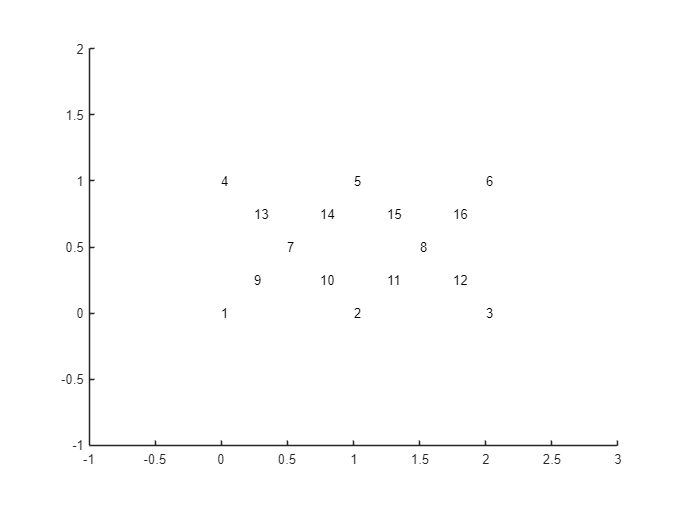

% Set up the plotting function for inspection
plots=Plot_2D_Mechanism();
plots.assembly=assembly;
% We will plot for the 2D mechnism assembly

plots.displayRange=[-1;3;-1;1;-1;2]; 
% Range of the plot
plots.viewAngle1=0;
plots.viewAngle2=0;
% Change the viewing angle

plots.Plot_Shape_Node_Number()

% Plot the nodal coordinates for inspection

We will continue to defing the bar and rotational springs. Please note that this process is also the same as Example 02.

% Define how bars are connected
% First we do the horizontal truss (bars)
bar.node_ij_mat=[1,9;
                 7,9;
                 7,14;
                 14,5; % 4 bars
                 4,13;
                 13,7;
                 7,10;
                 10,2; % 8 bars
                 2,11;
                 11,8;
                 8,16;
                 16,6; % 12 bars
                 5,15;
                 15,8;
                 8,12;
                 12,3;]; % 16 bars

% Define the area of the bars
% We have a total of 16 bars
bar.A_vec=barA*ones(16,1);
bar.E_vec=barE*ones(16,1);

Let's first plot the bar elements to see if everything looks good. 

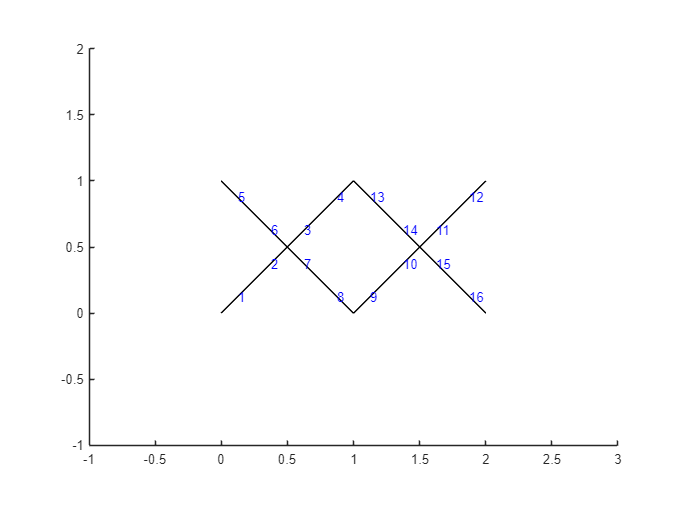

% Initialize the entire assembly 
assembly.Initialize_Assembly();
% Set up the 
plots.Plot_Shape_Bar_Number()


% Define how rotational springs are connected
rot_spr_3N.node_ijk_mat=[1 9 7;
                         9 7 14;
                         7 14 5; % 3 springs
                         4 13 7; 
                         13 7 10; 
                         7 10 2; % 6 springs
                         2 11 8; 
                         11 8 16; 
                         8 16 6; % 9 springs
                         5 15 8;  
                         15 8 12; 
                         8 12 3;]; % 12 springs

Here, we do not need to add the #13 spring to control the deployment so we will skip that. Therefore, the "rot_spr_K_vec" is now a 12 by 1 vector.

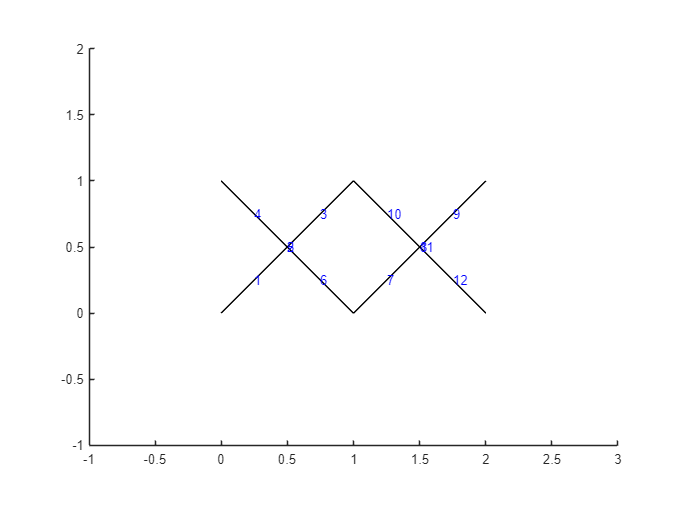

% Define rotational stiffness
rot_spr_3N.rot_spr_K_vec=kspr*ones(12,1);
% Initialize the entire assembly again for the new rot-spring
assembly.Initialize_Assembly();
% Plot the rotational spring number
plots.Plot_Shape_Spr_Number

Here, because we want to study the loading behavior, we need the "NR_Loading" solver. Please note that the support information is not the same as the Example 02. I encourage you to compare them to get a better understanding of the support definition. 

%% Set up the loading solver
nr=Solver_NR_Loading;
nr.assembly=assembly;
nr.supp=[1,1,1,1;
         2,0,1,0;
         3,1,1,1;
         4,0,1,0;
         5,0,1,0;
         6,0,1,0;
         7,0,1,0;
         8,0,1,0;
         9,0,1,0;
         10,0,1,0;
         11,0,1,0;
         12,0,1,0;
         13,0,1,0;
         14,0,1,0;
         15,0,1,0;
         16,0,1,0;];

For the load, we put a -50 N load in the Z direction at node 2. This is at the mid span of the scissor mechanism and is just like what we want to match the first figure. 

% Set up the load
nr.load=[2,0,0,-1];

We will compute the deployment in 10-steps. Each step, we allow a maximum of 30 iterations to find the equilibrium using the Newton's method.

% Set up the total loading step
nr.increStep=5;
% Set up the maximum iteration
nr.iterMax=30;
% Set up the tolorence
nr.tol=10^-6;

Now that everything is creatd, we can ask the program to find the loading deformation history Uhis for us. This is done by asking the solver object "nr" to perform the "Solve()" function. 

% Solve for the deformation history
Uhis=nr.Solve();

Loading Analysis StartIcrement = 1
    Iteration = 1, R = 1.442464e-01
    Iteration = 2, R = 7.857457e-03
    Iteration = 3, R = 1.603933e-03
    Iteration = 4, R = 1.604759e-04
    Iteration = 5, R = 1.201807e-05
    Iteration = 6, R = 4.213858e-08
Icrement = 2
    Iteration = 1, R = 1.524910e-01
    Iteration = 2, R = 7.744854e-03
    Iteration = 3, R = 2.075243e-03
    Iteration = 4, R = 2.014100e-04
    Iteration = 5, R = 1.501627e-05
    Iteration = 6, R = 8.231193e-08
Icrement = 3
    Iteration = 1, R = 1.631522e-01
    Iteration = 2, R = 8.015425e-03
    Iteration = 3, R = 5.086208e-03
    Iteration = 4, R = 8.290968e-04
    Iteration = 5, R = 1.757964e-04
    Iteration = 6, R = 2.468579e-06
    Iteration = 7, R = 3.268121e-08
Icrement = 4
    Iteration = 1, R = 1.827928e-01
    Iteration = 2, R = 9.002369e-03
    Iteration = 3, R = 6.986916e-03
    Iteration = 4, R = 1.423932e-03
    Iteration = 5, R = 4.861989e-04
    Iteration = 6, R = 9.113422e-06
    Iteration = 7, R = 2.3

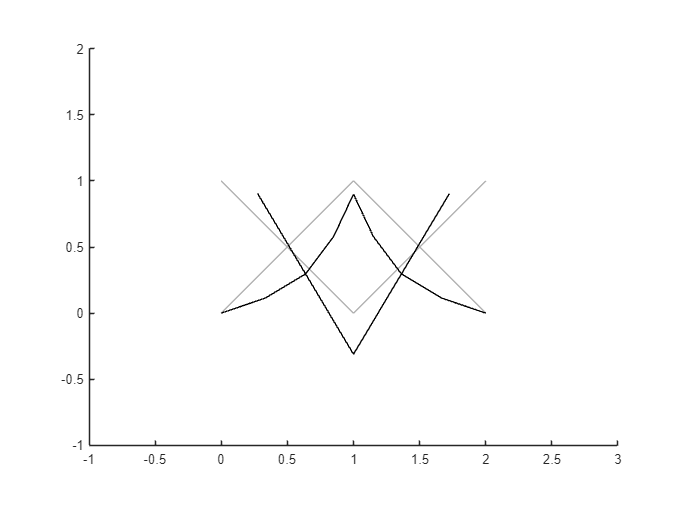

% Plot the deformed shape
plots.Plot_Deformed_Shape(squeeze(Uhis(end,:,:)));

Oh no! Look at that deformation with just 5N of load! The two truss buckle very hard at this small load. 

To practice, please consider further working out the following problems. 

**Problem 01 **

Turn this system into a cantilever beam and see what happens. As the following figure: